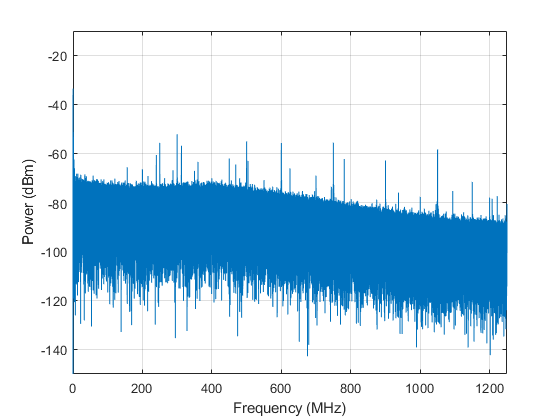

%% introduction
% ************************************************************************
% compute and plot PSD of instrument noise floor
% *************************************************************************
% working enviroment: Matlab 2008b and above
% Author: Liu Zhixin @ UCL
% Date created: Nov.02, 2021
% Date of last major modification: Nov.15, 2021
% copyright @ Zhixin Liu, all rights reserved,
% CC-BY, for teaching and education
% *************************************************************************
clc; clear; close all;format long;
% data path - change this to your own data path (suggest using your own onedrive)
% datapath = 'testdata\SNR\';
% read data and calculate
waveform_filename = 'CH1_task1.CSV';
waveform_filename = strcat(waveform_filename);
data = csvread(waveform_filename,1,0);
T = data(:,1); % time [s]
Waveform = data(:,2) - mean(data(:,2)); % amplitude [V]
% get parameters (fill in the following lines)
dt = mean(T(2:end)-T(1:end-1)); % sampling period
fs = 1/dt; % sampling rate
N = numel(T); % number of samples
df = fs/N; % bandwidth of each frequency bin
%% Calcualte and plot PSD
% frequencies correspond to the samples in frequency domain
f = [0:N/2-1 -N/2:-1].' * (fs / N);
% calculate the Fourier transform of the complex envelope
Ampf = fft(Waveform) * dt;
% calculate the real and img part
realAmpf = real(Ampf(1:N/2)).^2;
imagAmpf = imag(Ampf(1:N/2)).^2;
absAmpf = realAmpf + imagAmpf;
% Then calculate the single-side band PSD (W/Hz)
psd = absAmpf/dt*2;
% ---- plot single-side band PSD in dBm ----
psd_dBm = 10*log10(psd*1000);
a = f(1:N/2)/1e6;
plot(f(1:N/2)/1e6,psd_dBm);
grid on; 
xlabel('Frequency (MHz)'); 
ylabel('Power (dBm)');
axis([0 f(N/2)/1e6 -150 -10]);

% --- total noise power ---
% total_noise_power = 10*log10(psd*df);
total_noise_power = 10*log10(trapz(psd));
fprintf('The noise power over the Nyquist bandwidth is %.2f dBm .\n',total_noise_power);

The noise power over the Nyquist bandwidth is -54.82 dBm .
